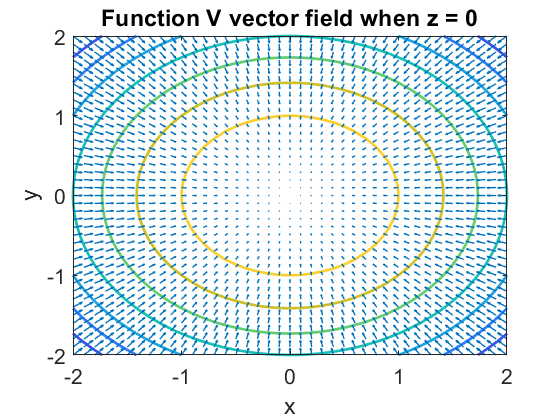

% STARTING PARAMETERS
% a(1) = x ; a(2) = y; a(3) = z
alfa = 0.2715;
gama = 0.1;
t_max = 10;
tspan = 0:.00005:t_max;

% 3D SYSTEM PLOT
f = @(t,a) [a(2)*(a(3)-1+a(1)^2)+gama*a(1); a(1)*(3*a(3)+1-a(1)^2)+gama*a(2); -2*a(3)*(alfa+a(1)*a(2))];
[t,a] = ode45(f,tspan,[10 10 10]);     % Runge-Kutta 4th/5th order ODE solver
plot3(a(:,1),a(:,2),a(:,3))

% 2D PLOTS ON DIFFERENT PLANES
% XOY then z=0
z=0;
sys=@(t,x) [x(2)*(z-1+x(1)^2)+gama*x(1); x(1)*(3*z+1-x(1)^2)+gama*x(2); -2*z*(alfa+x(1)*x(2))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for y0=-50:sep:50
[ts,xs] = ode45(sys,tspan,[x0 y0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when z = 0');
xlabel('x');
ylabel('y');
end
end
axis([-20 20 -50 50]);
set(gca,"FontSize",16)
hold off

% XOZ then y=0
y=0;
sys=@(t,x) [y*(x(2)-1+x(1)^2)+gama*x(1); x(1)*(3*x(2)+1-x(1)^2)+gama*y; -2*x(2)*(alfa+x(1)*y)];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for x0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[x0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when y = 0');
xlabel('x');
ylabel('z');
end
end
axis([-20 20 -50 50]);
set(gca,"FontSize",16);
hold off


% YOZ then x=0
xx=0;

sys=@(t,x) [x(1)*(x(2)-1+xx^2)+gama*xx; xx*(3*x(2)+1-xx^2)+gama*x(1); -2*x(2)*(alfa+xx*x(1))];
figure(1)
vectorfield(sys,-20:2:20,-50:2:50);
hold on
sep=5;
for y0=-20:sep:20
for z0=-50:sep:50
[ts,xs] = ode45(sys,[0 t_max],[y0 z0 0]);
plot(xs(:,1),xs(:,2))
title('Vector field when x = 0');
xlabel('y');
ylabel('z');
end
end
axis([-20 20 -50 50]);
set(gca,"FontSize",16);
hold off


% LYAPUNOV EXPONENT CALCULATION
syms l
A = [0.1 -1 0 ; 1 0.1 0; 0 0 -0.543]
eig(A)

A = [0.1 -1 0 ; 1 0.1 0; 0 0 -0.543]
P = lyap(A, eye(3))

% V MATRIX CALCULATION
syms x y z
V = [x y z]*P*[x; y; z]

% 2D AND 3D VECTORFIELD CALCULATION
clc;
u = -2:0.1:2;
Z=0;
[X,Y] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when z = ',num2str(Z)]);
xlabel('x');
ylabel('y');
set(gca,"FontSize",16);

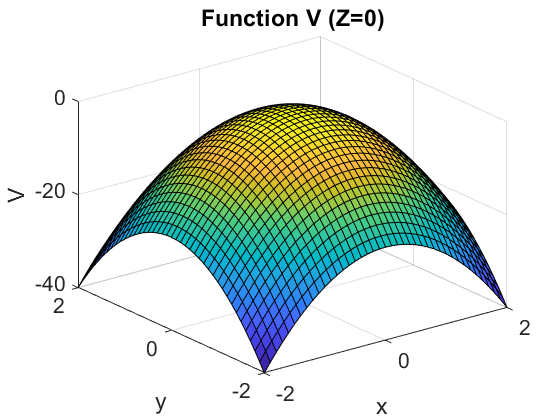

figure(2)
surf(X,Y,V);
xlabel('x');
ylabel('y');
zlabel('V');
title('Function V (Z=0)');
set(gca,"FontSize",16);

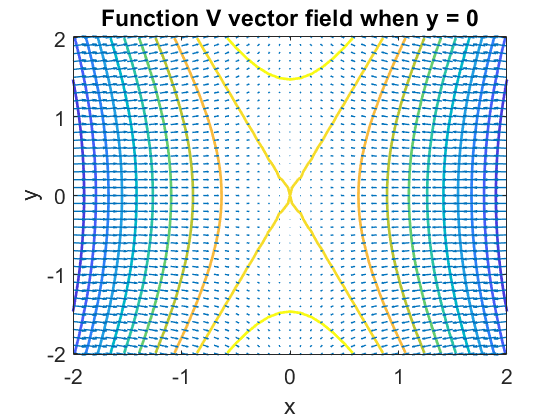


clc;
u = -2:0.1:2;
Y=0;
[X,Z] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when y = ',num2str(Y)]);
xlabel('x');
ylabel('y');
set(gca,"FontSize",16);

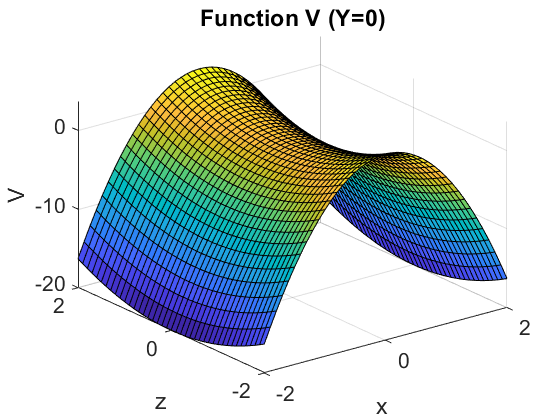


% axis equal;
figure(2)
surf(X,Z,V);
xlabel('x');
ylabel('z');
zlabel('V');
title('Function V (Y=0)');
set(gca,"FontSize",16);

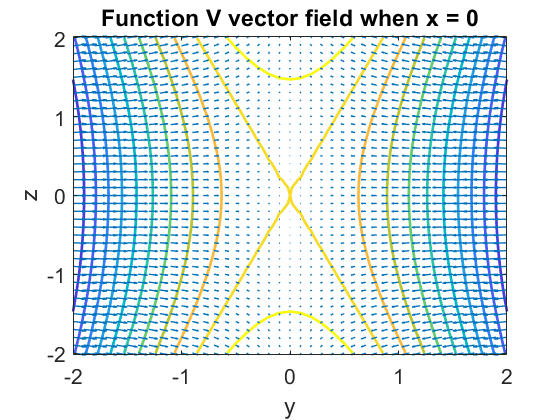


clc;
u = -2:0.1:2;
X=0;
[Y,Z] = meshgrid(u);
V = (500/543)*Z.^2-X.*(5*X-(3/18014398509481984)*Y)-Y.*((3/18014398509481984)*X+5*Y);
[px,py] = gradient(V,.2,.2);
figure(1)
contour(u,u,V,'linewidth',2)
hold on
quiver(u,u,px,py,'linewidth',1)
hold off
title(['Function V vector field when x = ',num2str(X)]);
xlabel('y');
ylabel('z');
set(gca,"FontSize",16);

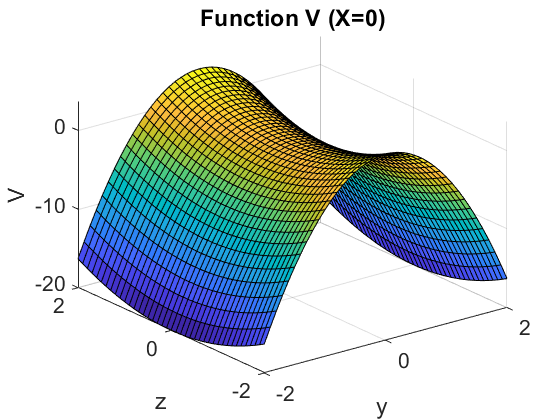

% axis equal;
figure(2)
surf(Y,Z,V);
xlabel('y');
ylabel('z');
zlabel('V');
title('Function V (X=0)');
set(gca,"FontSize",16);